load uspsDigits.mat;
% fix so is uses the centroid of the training data and check vs the test
% data

% centroid metoden (mot 1 centroid - typ värdelös)
% fix loop and check tempDiff
%ima(testDigits(:,:,1))
randImgIndex = randi(2007)

randImgIndex = 1636

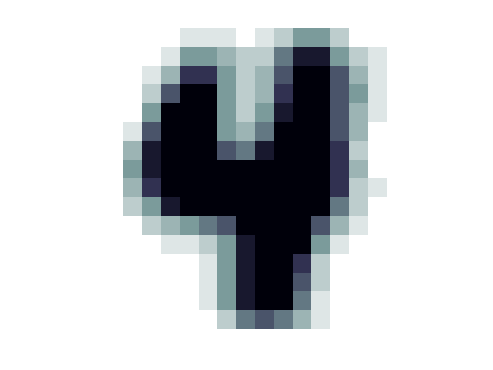


indexDigit = find(testAns == 4);

%mean(testDigits(indexDigit),3)
sumDigit = zeros(16,16,1);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,1) = sumDigit(:,:,1) + testDigits(:,:,indexValue);
end
meanDigit = sumDigit./length(indexDigit);
ima(testDigits(:,:,randImgIndex))
ima(meanDigit)


testAns(randImgIndex)

ans = 1

%tempDiff = abs(norm(meanDigit(:,:,1)) - norm(testDigits(:,:,randImgIndex)))
tempDiff = abs(norm(meanDigit(:,:,1) - testDigits(:,:,randImgIndex))) % this is the right one?

tempDiff = 5.0777

% centroid metoden
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1818

results = zeros(10,1);
sumDigit = zeros(16,16,10);
for dig = 0:9
    indexDigit = find(testAns == dig);
    
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        testDigits(:,:,indexValue);
        sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
    end
    meanDigit = sumDigit./length(indexDigit);
    tempDiff = abs(norm(meanDigit(:,:,dig + 1) - testDigits(:,:,randImgIndex)));
    results(dig + 1) = tempDiff;
end
results

results =     5.0755
    4.7050
    4.0304
    3.5691
    2.8609
    3.6517
    4.5652
    2.6366
    3.3276
    1.6404


[M,I] = min(results);
minDigit = I-1

minDigit = 9

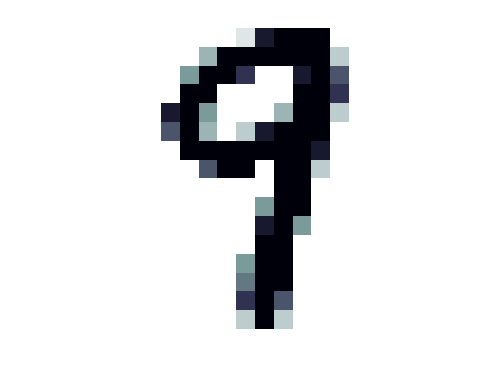

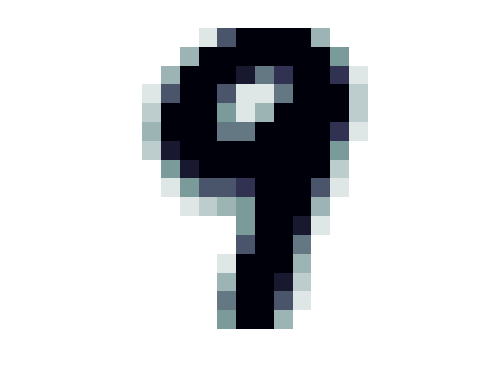

ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))

% closest neighbooooor
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 255

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;
for c = 1:2007
    if c ~= randImgIndex
        %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
        tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            savedIndex = c;
        end
    end
end 
savedIndex

savedIndex = 899

savedDiff

savedDiff = 5.8168

testAns(randImgIndex)

ans = 8

testAns(savedIndex)

ans = 8

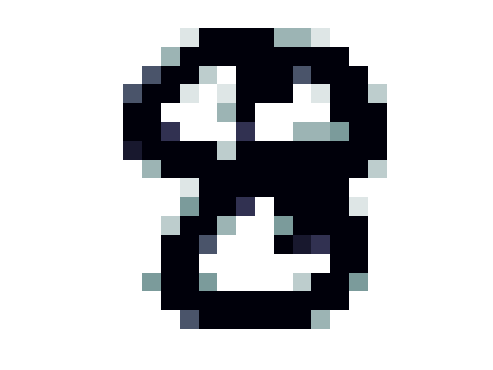

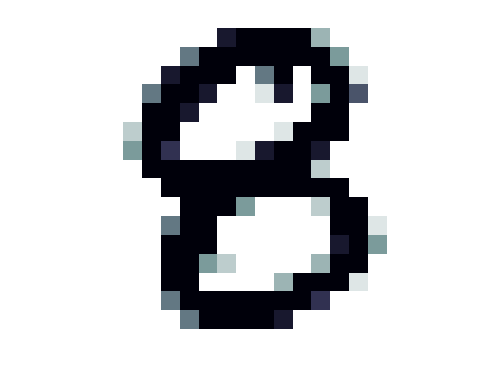

ima(testDigits(:,:,randImgIndex))
ima(testDigits(:,:,savedIndex))

% 5 closest neighbooors 
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1834

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;

nClosesNeighbooorIndex = [0;0;0;0;0];
nClosesNeighbooorValues = [savedDiff;savedDiff;savedDiff;savedDiff;savedDiff];

for n = 1:5
    for c = 1:2007
        if c ~= randImgIndex && c ~= nClosesNeighbooorIndex(1) && c ~= nClosesNeighbooorIndex(2) && c ~= nClosesNeighbooorIndex(3) && c ~= nClosesNeighbooorIndex(4) && c ~= nClosesNeighbooorIndex(5)
            %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
            tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));

            for j = 1:5
                if tempDiff < nClosesNeighbooorValues(j)
                    nClosesNeighbooorValues(j) = tempDiff;
                    nClosesNeighbooorIndex(j) = c;
                    break;
                end
            end
        end
    end 
end

nClosesNeighbooorIndex

nClosesNeighbooorIndex =         1824
        1598
        1651
        1215
        1201


testAns(nClosesNeighbooorIndex)

ans =      1
     1
     1
     1
     1


disp(['The most common number is (multiple values occurring equally frequently, ' newline 'mode returns the smallest of those values):'])

The most common number is (multiple values occurring equally frequently, 
mode returns the smallest of those values):


mode(testAns(nClosesNeighbooorIndex))

ans = 1

nClosesNeighbooorValues

nClosesNeighbooorValues =     0.7673
    0.7769
    0.8034
    0.8385
    0.9067


testAns(randImgIndex)

ans = 1